Proyecto

data = readtable('count_per_month.csv')

data = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Probando con las fechas
%datetime(,'InputFormat','yyyy/MM/dd HH:mm:ss.S')
date = data{1,"releaseDate"}

date = 1×1 cell array
    {'2010-02'}


class(date)

ans = 'cell'

datetime(datatable{:,'releaseDate'},'InputFormat','yyyy-MM')

ans = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


% Probando la clase MobileAppDataset
objDataset = MobileAppDataset('count_per_month.csv')

objDataset =   MobileAppDataset with no properties.


objDataset.getData()

ans = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Accediendo a datos con expresiones
datatable = objDataset.getData();
datatable{1,'releaseDate'}{:}

ans = '2010-02'

% Método getCountPerMonth() de la clase MobileAppDataset
[fechas, cantidades] = objDataset.getCountPerMonth()

fechas = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


cantidades =      1
     1
     1
     2
     1
     1
     1
     1
     1
     4


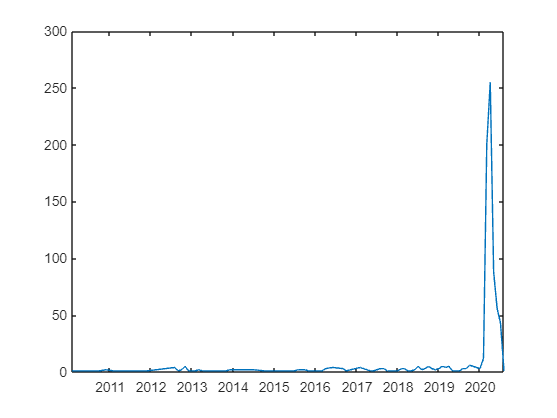

plot(fechas, cantidades)